% Real data for bulgar wheat
% Source: https://www.researchgate.net/publication/43257218_Root-zone_salinity_I_Selecting_a_product-yield_index_and_response_function_for_crop_tolerance
x = [0.98 1.55 2.10 3.12 4.06 5.30 6.04 8.17 9.97 12.10 13.80]';
y = [307 306.9 282.9 234.9 225.4 170.0 111.0 82.6 64.5 19.9 15.0]';
y = y./max(y)

y =     1.0000
    0.9997
    0.9215
    0.7651
    0.7342
    0.5537
    0.3616
    0.2691
    0.2101
    0.0648


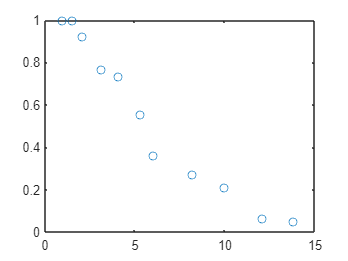

plot(x,y,"o")

fun = @(b,x) 1./(1+(x./b(1)).^exp(b(2)));
b0 = [7 1.5]

b0 =     7.0000    1.5000


mdl = fitnlm(x,y,fun,b0)

mdl = Nonlinear regression model:
    y ~ 1/(1 + (x/b1)^exp(b2))

Estimated Coefficients:
          Estimate       SE       tStat       pValue  
          ________    ________    ______    __________

    b1     5.4386      0.16986    32.019    1.3891e-10
    b2    0.99987     0.080985    12.346    6.0405e-07


Number of observations: 11, Error degrees of freedom: 9
Root Mean Squared Error: 0.0432
R-Squared: 0.987,  Adjusted R-Squared 0.986
F-statistic vs. zero model: 1.21e+03, p-value = 1.15e-11

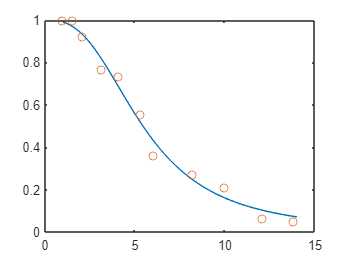

xnew = 1:0.01:14;
plot(xnew',predict(mdl,xnew'),"-")
hold on
plot(x,y,"o")
hold off

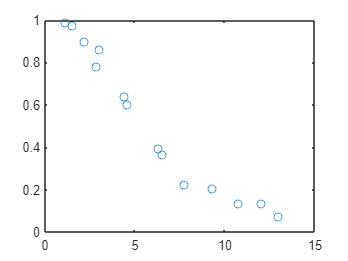

%for k =1:12:502
rng(457)
mdl2 = fitlm(1:11,x,"quadratic");
x1 = random(mdl2,(0.9:0.7:11)');
weights = 0.75+1.5*rand(size(x1));
weights(1:4) = 10;
y1 = random(mdl,x1,"Weights",weights);
x1(y1>=1)=[];
y1(y1>=1)=[];
plot(x1,y1,"o")

% title(k)
%drawnow
%end

x = (x1)'

x =     1.1402    1.5018    2.1769    2.8529    3.0455    4.4065    4.5619    6.3254    6.5271    7.7574    9.3182   10.7265   12.0114   12.9557


y = (y1*295)'

y =   291.0686  287.5483  264.9736  229.7256  254.3437  188.4811  178.0081  115.7590  107.3457   65.5061   61.0981   39.4420   39.0315   21.8798


save nonlinearData.mat x y